# Tipos de datos: Números

## Números de punto flotante y notación científica

### Ejercicio

Utilizando el mismo código del ejemplo de la teoría, modificar el límite máximo, `maxL`, tal que no haya diferencia entre utilizar números de precisión doble o números de precisión sencilla.

**Nota 1:** Como se vio en el ejemplo, con `1e8` (${10}^8$) hay una clara diferencia entre ambos tipos de números de punto flotante. Por lo tanto, habría que probar números más pequeños, `1e4` (${10}^4$) por ejemplo, para determinar hasta dónde podemos trabajar con estos números tal que no haya esa diferencia.

**Nota 2:** No modificar el resto del código.

*Ejemplo modificado de Moore, 2007.*

### Solución

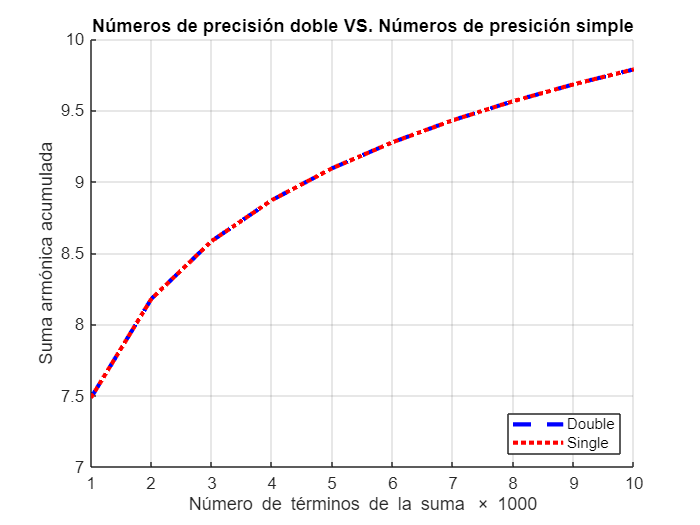

clear

% Límites de la suma.
maxL = 1e4;     %linea modificada
idx = 1e3:1e3:maxL;

% Suma armónica acumulada con números de precisión doble.
nDou = 1:maxL;
nDou = 1 ./ nDou;
serieArmDouble = cumsum(nDou);

% Suma armónica acumulada con números de precisión simple.
nSing = single(1:maxL);
nSing = 1 ./ nSing;
serieArmSingle = cumsum(nSing);

% Visualización de las sumas.
figure("Name", "Serie armónica: Double VS. Single")
hold on
plot(serieArmDouble(idx), "b--", "LineWidth", 2.5, "DisplayName", "Double");
plot(serieArmSingle(idx), "r:", "LineWidth", 2.5, "DisplayName", "Single");
hold off

% Mejoramiento de la visualización.
title("Números de precisión doble VS. Números de presición simple")
ylabel("Suma armónica acumulada")
xlabel("Número de términos de la suma \times 1000")
legend("Location", "southeast")
grid

% set(gca, "FontSize", 16, "LineWidth", 1.5)

## Números enteros

### Ejercicio

El archivo `Tema02_Auxiliar_BankChurners.mat` contiene información sobre un par de miles de cuentas bancarias de los clientes de un banco, como el número de cuenta, la edad, el nivel de estudios, la capacidad adquisitva, etc.

Cargar las variables `CLIENTNUM`, `CreditLimit`, `CustomerAge` y `MonthsInactive` del archivo `Tema02_Auxiliar_BankChurners.mat`. Convierta estas variables en un tipo de número entero. ¿Es correcto afirmar que todas las variables deberían ser de tipo entero? ¿Por qué?

### Solución

clear
load Tema02_Auxiliar_BankChurners.mat CLIENTNUM CreditLimit CustomerAge MonthsInactive
whos

  Name                    Size            Bytes  Class     Attributes

  CLIENTNUM           10127x1             81016  double              
  CreditLimit         10127x1             81016  double              
  CustomerAge         10127x1             81016  double              
  MonthsInactive      10127x1             81016  double              



uint16(CLIENTNUM)

ans = 10127×1 uint16 column vector
   65535
   65535
   65535
   65535
   65535
   65535
   65535
   65535
   65535
   65535


int16(CreditLimit)

ans = 10127×1 int16 column vector
   12691
    8256
    3418
    3313
    4716
    4010
   32767
   29081
   22352
   11656


uint16(CustomerAge)

ans = 10127×1 uint16 column vector
   45
   49
   51
   40
   40
   44
   51
   32
   37
   48


uint16(MonthsInactive)

ans = 10127×1 uint16 column vector
   1
   1
   1
   4
   1
   1
   1
   2
   2
   3


## Formatos de visualización

### Ejercicio

La presión se define como


$$P=\frac{F}{A}$$


donde $P$ es la presión en Pascales ($\textrm{Pa}$), $F$ es la fuerza en Newtons ($\mathrm{N}$) y $A$ es el área en metros cuadrados (${\mathrm{m}}^2$).

Determinar la presión que ejercen $147\;450\;\mathrm{N}$ en un área de $0\ldotp 014\;{\mathrm{m}}^2$. 

**Nota 1:** Las operaciones aritméticas se estudian más a pronfudadid un poco más adelante. Sin embargo, la división de dos números se realiza como se muestra a continuación:

**Nota 2:** Recordar que para una fácil y directa visualización en cálculos que involucren unidades, y prefijos, son útiles los estilos `shortEng` y `longEng`.

### Solución

format shortEng 
F= 147450;         %fuerza [N]
A= 0.014;          %área [m^2]
P=F/A              %Presión [Pa]

P =     10.5321e+006


Esto nos indica que el resultado está en Mega --> p  = 10.5 [MPa]

## Operaciones aritméticas

### Ejercicio 1

Realizar las siguientes operaciones:

- 
$$\frac{5+2}{{12}^2 }$$


- 
$$\sqrt{{\left(2+\pi \right)}^2 +1}$$


- 
$$7+\frac{5}{3^4 }\times \frac{8^{-4} }{1\ldotp 5}$$


### Solución

%operación uno
(5+ 2)/12^2

ans = 0.0486

%operación dos
sqrt((2 + pi)^2 + 1)

ans = 5.2379

%operación tres 
7 + (5/3^4)*(8^-4 / 1.5)

ans = 7.0000

### Ejercicio 2

Un estudiante de ingeniería posee 53 libros que ha utilizado a lo largo de su carrera universitaria. Sin embargo, dado que ya finalizó sus estudios, quiere guardar todos los libros. Únicamente dispone de 3 cajas. ¿Cuántos libros podrá guardar en cada caja? ¿Cuántos libros no entrarán en las cajas?

Si el estudiante ha contado mal y en realidad ha tenido 49 libros, ¿todos éstos ya entrarían en las cajas sin que quede alguno fuera?

### Solución

%considerando 53 libros 
l=53;         %número de libros 
c=3;          %número de cajas 
rdivide(l,c)  %nos dará el número de libros en cada caja 

ans = 17.6667

rem(l,c)      %nos dará el residúo

ans = 2

Esto quiere decir que no podría guardar todos los libros ya que le quedarían 2 afuera y en cadda caja podrían haber 17 libros en cada caja.

En cambio si solo son 49 libros, si podrían camber, aunque en la última caja solo habría 15 libros.

### Ejercicio 3

Definir las siguientes variables:

Seguidamente, cambiar el formato de visualización a `bank` y:

- Calcular el costo de dos mesas y ocho sillas.

- Realizar el literal 1 de nuevo, pero añadir un 5.5% de IVA.

*Ejercicio modificado de Gilat, 2006.*

### Solución

precio_mesa = 256.95;    % Precio en dólares [$].
precio_illa = 89.99;     % Precio en dólares [$].
format bank
costo1= 2*precio_mesa + 8*precio_illa

costo1 =        1233.82


costo2= costo1 + costo1*0.05

costo2 =        1295.51


## Orden de las operaciones aritméticas

### Ejercicio

Antes de realizar las siguientes operaciones aritméticas, ¿cuál cree que sea el resultado?

- 2+5/10

- 2*3+3*2

- 2^0*5

- 1+2+3/3*2+1

- (1+2+3)/(3*2+1)

Ahora compruébelo dentro de MATLAB.

### Solución

2+5/10

ans = 2.5000

2*3+3*2

ans = 12

2^0*5

ans = 5

1+2+3/3*2+1

ans = 6

(1+2+3)/(3*2+1)

ans = 0.8571